clc
clear
model.Parameters
Ks = zeros(1,3,4);
for i=1:4
    [T_wOP, q_OP, alpha, omega_s_OP, omega_OP] = control.calculateOperatingPoint(273.15+20,i,param);
    param.ctrl.alpha(i) = alpha;
    param.ctrl.T_wOP(i) = T_wOP;
    param.ctrl.T_aOP(i) = 273.15+20;
    param.ctrl.omega_OP(i) = omega_OP;
    param.ctrl.omega_s_OP(i) = omega_s_OP;
    param.ctrl.q_OP(i) = q_OP;
end
param.ctrl.Ks(:,:,1) =[-0.0669, 0.3820, 0.0769];
param.ctrl.Ks(:,:,2) = [-0.0390, 0.2228, 0.0449];
param.ctrl.Ks(:,:,3) = [-0.0334, 0.1910, 0.0385];
param.ctrl.Ks(:,:,4) =[-0.0557,0.3184, 0.0641];

simtime = 10*60;

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end

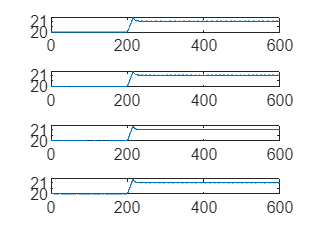

figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0,options);

coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);


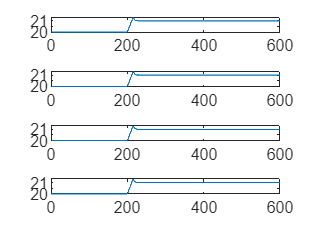

figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,1)-273.15)
end